# gen sound 분석

시뮬레이션 소리는 30초짜리, 하나의 소리만 들어가있음

clear, clc, close all

% 시뮬레이션 소리 경로
path0 = "C:/Users/" + getenv('username') +"/Desktop/DCASE2024-Task10-Dataset/simulation/";
gen_name = "gen_sound_v3/";
train_name = replace(gen_name, '/' ,'') + ".csv";

train_path = path0 + train_name;
data_info = readtable(train_path);
len_data = height(data_info);

data_nn = 1; % 1~600(len_data)
filepath = path0 + data_info.path{data_nn}

filepath = "C:/Users/yeon/Desktop/DCASE2024-Task10-Dataset/simulation/gen_sound_v3/loc1_1.flac"

[sig, fs] = audioread(filepath);
tt = (0:length(sig)-1)/fs;

sig = sig/(max(abs(sig(:))));

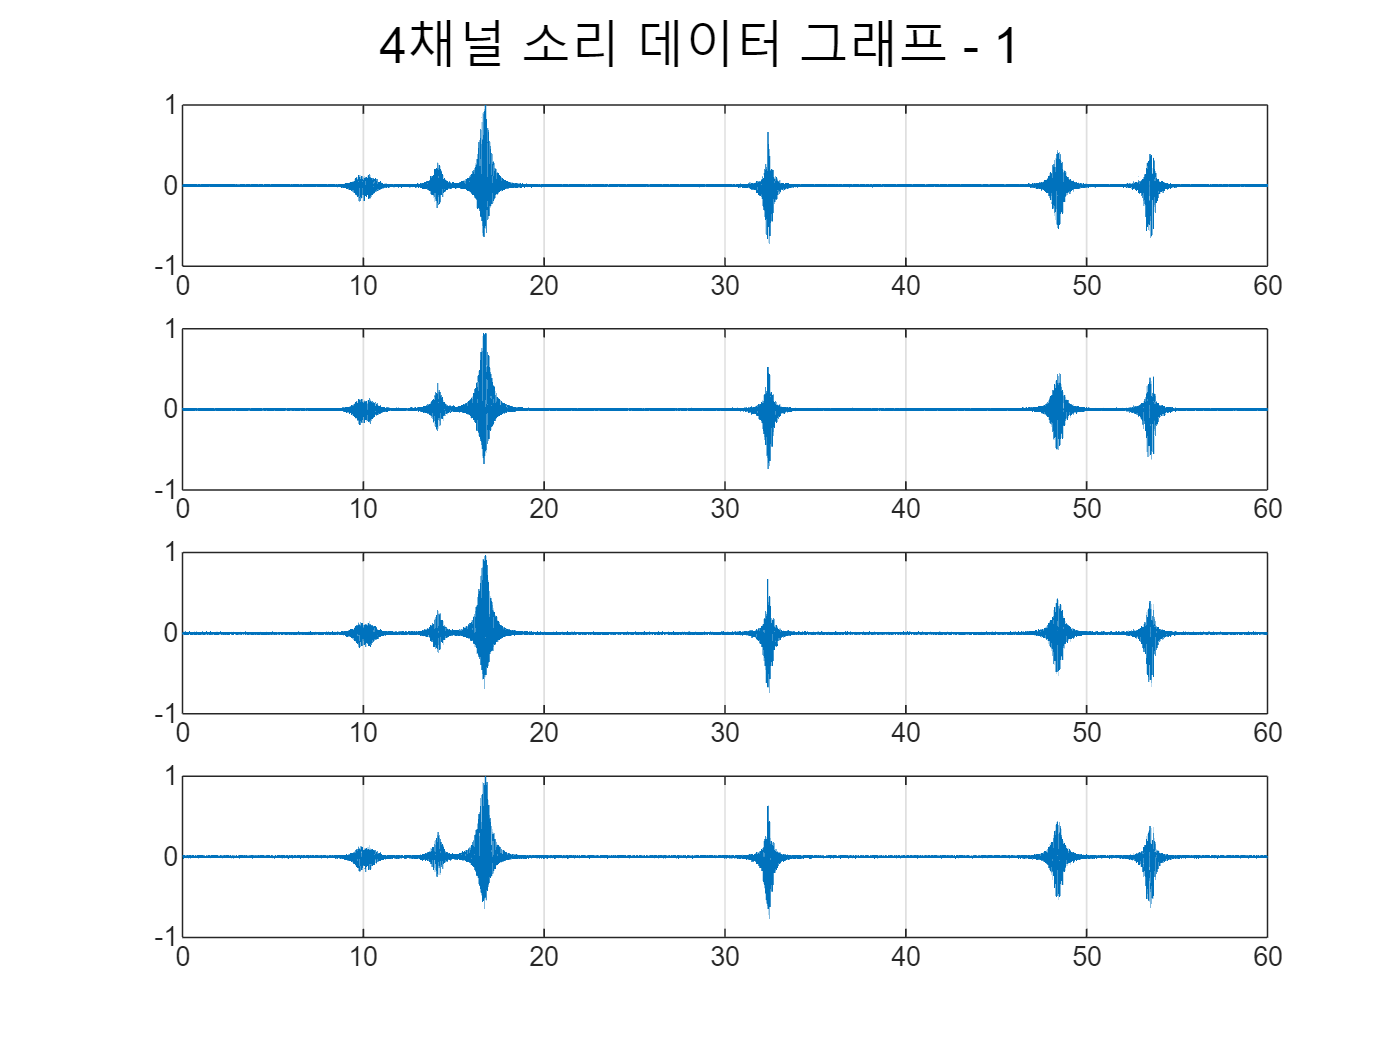

figure("Name", gen_name+"1"), sgtitle("4채널 소리 데이터 그래프 - " + data_nn)
for nn = 1:4
    subplot(4,1,nn), plot(tt, sig(:,nn)), grid
end

fframe = 2^10;
delay = fframe/4;
sum_sig = sum_2sig_with_delay(sig, delay);

sthds = {};

tic
parfor nn = 1:6
    sthds{nn} = stHD(sum_sig(:,nn), fs, fframe);
end
toc

경과 시간은 1.501116초입니다.


size(sthds{1})

ans =         1024        1874


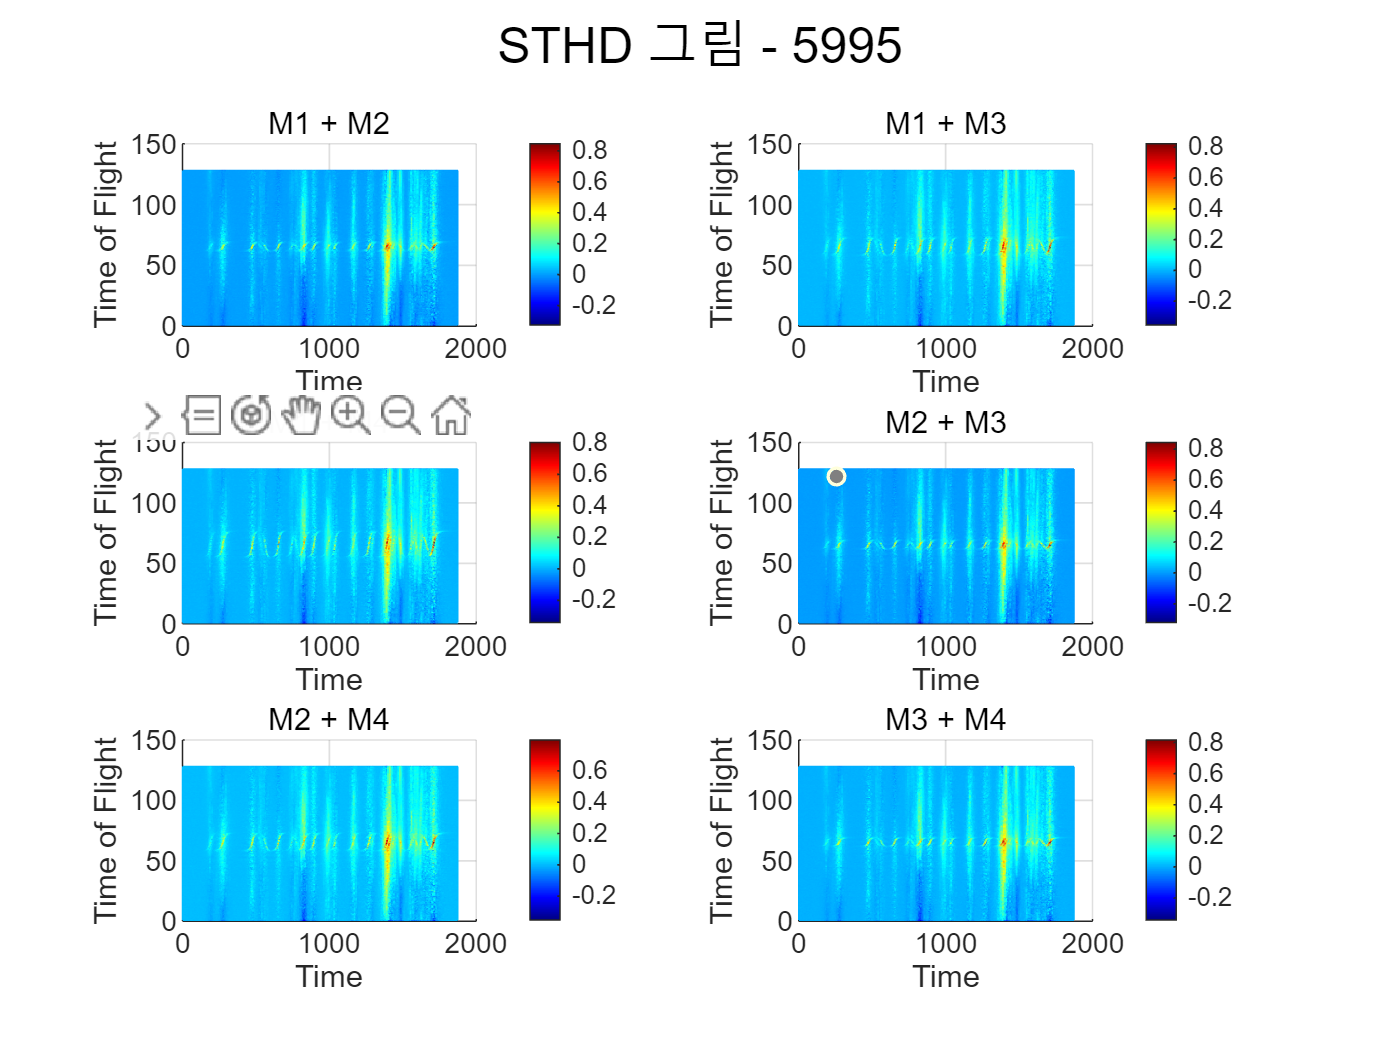

sig_name = {'M1 + M2', 'M1 + M3', 'M1 + M4', 'M2 + M3', 'M2 + M4', 'M3 + M4'};
% mesh_xlim = 1:fframe/2;
mesh_xlim = fframe/4-fframe/16+1:fframe/4+fframe/16;

figure("Name", gen_name+"2"), sgtitle("STHD 그림 - " + data_nn)
for nn = 1:6
    sthd = sthds{nn};
    sthd = sthd(mesh_xlim,:);
    
    subplot(3,2,nn),
    mesh(sthd, 'FaceColor', 'flat'), colormap(jet), colorbar, view([0 90]),
    title(sig_name{nn}), xlabel('Time'), ylabel('Time of Flight'), xlim([1 1874]), ylim([1 128])    
end

% 레이블
label_name = ["car_l2r", "car_r2l", "cv_l2r", "cv_r2l"];
label = [data_info.car_left(data_nn) data_info.car_right(data_nn) data_info.cv_left(data_nn) data_info.cv_right(data_nn)]

label =     10    20     3     4


## Spectrogram 그리기

stft로 계산하고 크기, 제곱을 mag2db를 하면 되나?

stfts = {};

tic
parfor nn = 1:4
     S = stft(sig(:,nn)+eps, fs, 'Window', hann(fframe,'periodic'), 'OverlapLength', fframe/2, 'FFTLength', fframe, 'FrequencyRange', 'onesided');      
     stfts{nn} = mag2db(abs(S.^2)+eps);
end
toc

경과 시간은 0.235628초입니다.


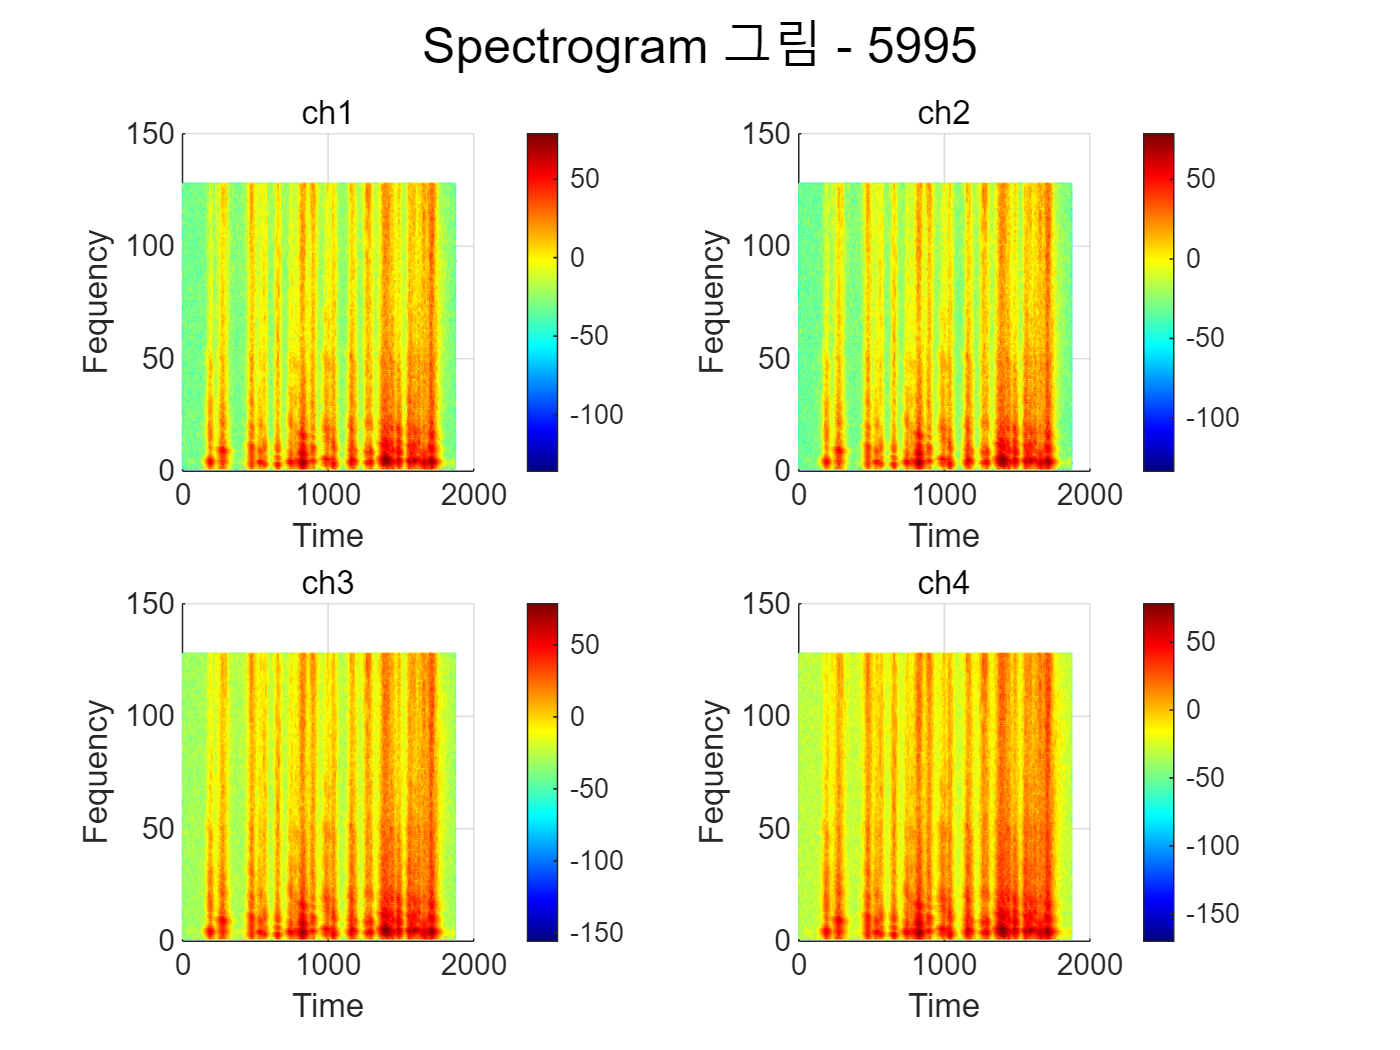

figure("Name", gen_name+"3"), sgtitle("Spectrogram 그림 - " + data_nn)
mesh_xlim = 1:fframe/8;

for nn = 1:4    
    subplot(2,2,nn),
    mesh(stfts{nn}(mesh_xlim,:), 'FaceColor', 'flat'), colormap(jet), colorbar, view([0 90]),
    title("ch" + nn), xlabel('Time'), ylabel('Fequency'), xlim([1 1874]), ylim([1 128])    
end